# Figure 6: Frs Comparison

clear

## 1. Read Files and get all Frs

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])
addpath([CurrentFolder '/HPCData/Figure6Validation'])

SCFileDir = [CurrentFolder '/HPCData/Figure6Validation/'];
List = dir(SCFileDir);

Fr_NW = [];
Fr_MF = [];
for FileInd = 1:length(List)
    if ~List(FileInd).isdir
        load(List(FileInd).name,'ContourData_7D')
        
        Fr_NW = [Fr_NW, ContourData_7D.Fr_NW];
        Fr_MF = [Fr_MF, ContourData_7D.Fr_NoFix_ref];
        clear ContourData_7D
        FileInd 
    end
end

FileInd = 3

FileInd = 4

FileInd = 5

FileInd = 6

FileInd = 7

FileInd = 8

FileInd = 9

FileInd = 10

FileInd = 11

FileInd = 12

FileInd = 13

FileInd = 14

FileInd = 15

FileInd = 16

FileInd = 17

FileInd = 18

FileInd = 19

FileInd = 20

FileInd = 21

FileInd = 22

FileInd = 23

FileInd = 24

FileInd = 25

FileInd = 26

FileInd = 27

FileInd = 28

FileInd = 29

FileInd = 30

FileInd = 31

FileInd = 32

FileInd = 33

FileInd = 34

Plot

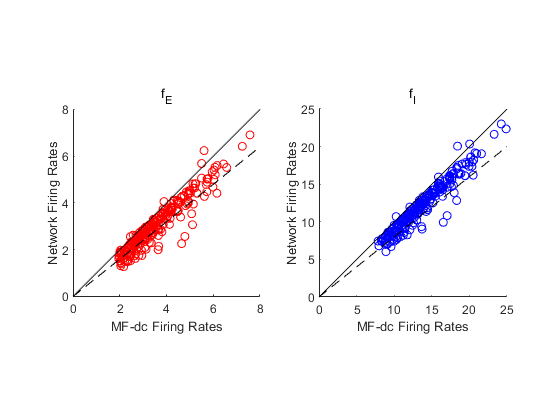

BadInd = (Fr_NW(1,:) == 0 | Fr_NW(1,:)> 12);

Fr_NWShow = Fr_NW(:,~BadInd);
Fr_MFShow = Fr_MF(:,~BadInd);

FindBound  = .8;
figure('Name','Figure6_SpotCheck')
subplot 121
hold on
scatter(Fr_MFShow(1,:),Fr_NWShow(1,:),'ro')
title('f_E')
ylabel('Network Firing Rates'); xlabel('MF-dc Firing Rates')
axis([0 8 0 8])
axis square
BGLine = 0:9;
plot(BGLine,BGLine,'k-')
plot(BGLine,(BGLine)*FindBound,'k--')
FineFrENum = sum(Fr_NWShow(1,:)./Fr_MFShow(1,:)<FindBound);

subplot 122
hold on
scatter(Fr_MFShow(2,:),Fr_NWShow(2,:),'bo')
title('f_I')
ylabel('Network Firing Rates'); xlabel('MF-dc Firing Rates')
axis([0 25 0 25])
axis square
BGLine = 0:25;
plot(BGLine,BGLine,'k-')
plot(BGLine,(BGLine)*FindBound,'k--')

FineFrINum = sum(Fr_NWShow(2,:)./Fr_MFShow(2,:)<FindBound);